Práctica 3

Ejercicio práctico 1. Extracción y dibujo de polos y ceros de funciones de transferencia

G1=tf([1],[1 0 4])

G1 =
 
     1
  -------
  s^2 + 4
 
Continuous-time transfer function.



polos1=pole(G1)

polos1 =    0.0000 + 2.0000i
   0.0000 - 2.0000i


zeros1=zero(G1)


zeros1 =

  0×1 empty double column vector



G2=tf([1],[1 4 6 4 1])

G2 =
 
                1
  -----------------------------
  s^4 + 4 s^3 + 6 s^2 + 4 s + 1
 
Continuous-time transfer function.



[polos2,zeros2]=pzmap(G2)

polos2 =   -1.0002 + 0.0000i
  -1.0000 + 0.0002i
  -1.0000 - 0.0002i
  -0.9998 + 0.0000i



zeros2 =

  0×1 empty double column vector



G3=tf([1 2 1],[1 -1 0])

G3 =
 
  s^2 + 2 s + 1
  -------------
     s^2 - s
 
Continuous-time transfer function.



[polos3,zeros3]=pzmap(G3)

polos3 =      0
     1


zeros3 =     -1
    -1


G4=tf([1 0 -1],[1 5 11 25 34 20 24])

G4 =
 
                       s^2 - 1
  --------------------------------------------------
  s^6 + 5 s^5 + 11 s^4 + 25 s^3 + 34 s^2 + 20 s + 24
 
Continuous-time transfer function.



[polos4,zeros4]=pzmap(G4)

polos4 =   -3.0000 + 0.0000i
  -2.0000 + 0.0000i
  -0.0000 + 2.0000i
  -0.0000 - 2.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i


zeros4 =     -1
     1


2. Para cada una de las funciones de transferencia, realiza una gráfica del plano complejo donde aparezcan dichos polos y ceros.

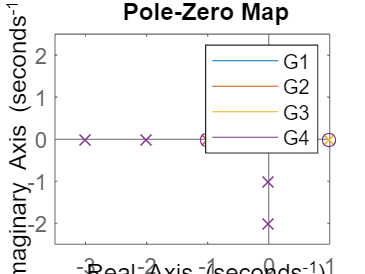

pzmap(G1,G2,G3,G4)
legend('G1','G2','G3','G4')

Ejercicio práctico 2. Polos y ceros en lazo abierto y en lazo cerrado en función de K 1. Realiza una gráfica del plano complejo con los polos y ceros de P(s): 𝑃𝑃(𝑠𝑠) = 𝑠𝑠 + 1 (𝑠𝑠 − 1)(𝑠𝑠 + 2)(𝑠𝑠 + 4) 

P=zpk([-1],[1 -2 -4],1)

P =
 
        (s+1)
  -----------------
  (s-1) (s+2) (s+4)
 
Continuous-time zero/pole/gain model.



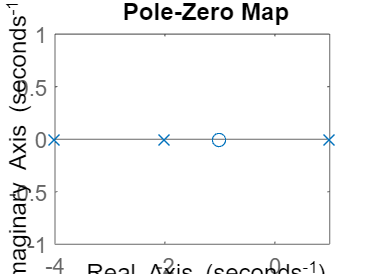

pzmap(P)

2. Realiza ahora una única gráfica de los polos y ceros de la función de transferencia en lazo cerrado GLC(s) del sistema de la figura, con la misma P(s) y con C(s) = K, para tres valores de la constante K, K=1, K=3 y K=10. ¿Influye el valor de K en la posición de los polos, de los ceros o de ambos en el sistema en lazo cerrado? Justifica tu respuesta

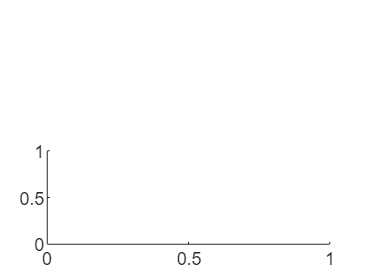

K_values = [1, 3, 10];
subplot(2, 1, 2);

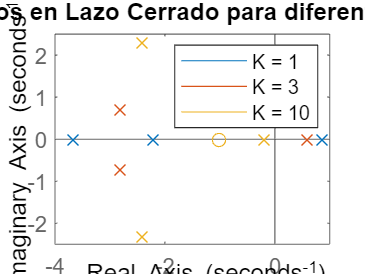

figure;hold on;

for K = K_values
    % Función de transferencia en lazo cerrado
    GCL = feedback(K * P, 1);
    
    % Polos y ceros de lazo cerrado
    pzmap(GCL);
end

title('Polos y Ceros en Lazo Cerrado para diferentes valores de K');
legend('K = 1', 'K = 3', 'K = 10');
hold off;

Ejercicio práctico 3. Respuesta temporal de sistemas de primer orden 1. Construye cinco funciones de transferencia de primer orden situando sus polos en s = -0.5, s=-1, s = -3, s = -5 y s = -10 respectivamente. 

G1 = zpk([], -0.5, 1);
G2 = zpk([], -1, 1);
G3 = zpk([], -3, 1);
G4 = zpk([], -5, 1);
G5 = zpk([], -10, 1);

2. Realiza una gráfica que incluya la respuesta al impulso unitario de todas ellas hasta un valor final de t = 5 s. Incluye la leyenda. Justifica el resultado obtenido. 

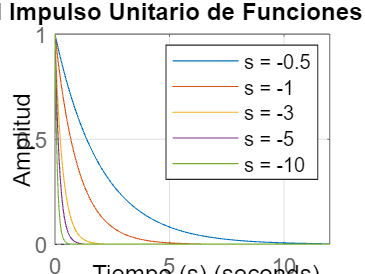

% Respuesta al impulso unitario de todas las funciones
figure;
impulse(G1, G2, G3, G4, G5);
legend('s = -0.5', 's = -1', 's = -3', 's = -5', 's = -10');
title('Respuesta al Impulso Unitario de Funciones de Primer Orden');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

3. Realiza ahora una gráfica que incluya la respuesta al escalón unitario de todas ellas hasta un valor final de t = 10 s. Incluye la leyenda. Justifica el resultado obtenido.

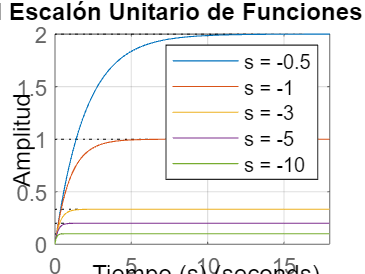

% Respuesta al escalón unitario de todas las funciones
figure;
step(G1, G2, G3, G4, G5);
legend('s = -0.5', 's = -1', 's = -3', 's = -5', 's = -10');
title('Respuesta al Escalón Unitario de Funciones de Primer Orden');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

4. Modifica la ganancia estática de cada una de las funciones anteriores para la respuesta al escalón de todas ellas tenga el mismo valor final igual a 1.

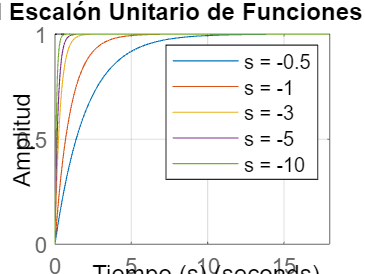

figure;
step(G1*0.5, G2, G3*3, G4*5, G5*10);
legend('s = -0.5', 's = -1', 's = -3', 's = -5', 's = -10');
title('Respuesta al Escalón Unitario de Funciones de Primer Orden');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;